# BIV Whirlpool-Galaxie Processing

## Preprocessing

Setup

dark_frame_file = "data/darkframe.tiff";
background_file = "data/background_fit.tiff";
raw_files = dir("data/raw/*.tiff");

addpath('code');

Load darkframe and compute hotpixels

hot_pixels = get_hotpixels(raw_files);

dark_frame = (imread(dark_frame_file));

Calibrate raw images by subtracting darkframe and hotpixels and de-bayering, then save them

n = numel(raw_files);

% Start progress bar
margin_from_edge = 20;
h = waitbar(0, 'Preprocessing raw images...');

parfor k = 1:n
    name = raw_files(k).name;
    img = imread(fullfile("data/raw/", name));
    
    img_calibrated = img - dark_frame - hot_pixels;
    img_calibrated(img_calibrated < 0) = 0; % Clip negatives

    img_rgb = demosaic(img_calibrated, 'rggb', BitsPerSample=16); % Get rgb values through de-bayering

    cropped_rgb = circular_crop(img_rgb, margin_from_edge); % Crop out the edges
    save_image(cropped_rgb, fullfile("data/calibrated_raw/", name));

    waitbar(k/n, h, sprintf('Preprocessing %d of %d images', k, n));
end

close(h);


## Stacking

Load Calibrated

calibrated_images = {};
n = numel(raw_files);
for k = 1:n
    name = raw_files(k).name;
    img = (imread(fullfile("data/calibrated_raw/", name)));
   
    calibrated_images{end+1} = img;
end


Reference image

reference = calibrated_images{1};

Align images to reference by detecting stars for tracking and matching them to the reference to create the necessary transformation

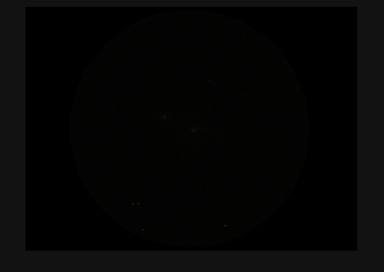

aligned_images = cell(size(calibrated_images));
aligned_images{1} = reference;
h = waitbar(0, 'Aligning images...');

% Detect stars
points_fixed  = get_star_tracking_points(reference);

parfor k = 2:n
    moving_image = calibrated_images{k};
    
    % Detect stars
    points_moving = get_star_tracking_points(moving_image);

    [matched_points, points_moving] = match_points(points_fixed, points_moving);
    
    % Find transform
    tform = estimateGeometricTransform2D(points_moving, matched_points, 'affine');
    
    % Warp image
    output_view = imref2d(size(reference));
    aligned = imwarp(moving_image, tform, "OutputView", output_view);
    
    aligned_images{k} = aligned;
    imshow(aligned);

    % Save aligned
    save_image(aligned, fullfile("data/aligned/", raw_files(k).name));

    waitbar(k/n, h, sprintf('Aligning %d of %d images', k, n));
end


close(h);

Stack images and use sigma clipping to filter noise by standard deviation

% preallocate
stack = zeros([size(aligned_images{1}), n], 'double');  % H x W x 3 x n

for k = 1:n
    stack(:,:,:,k) = im2double(aligned_images{k});
end

% Compute mean and std per pixel
pixel_mean = mean(stack, 4);
pixel_std  = std(stack, 0, 4);

% Sigma-clipping threshold
k = .12;
mask = abs(stack - pixel_mean) <= k*pixel_std;

% Compute sigma-clipped mean
stack_sum = sum(stack .* mask, 4);
counts = sum(mask, 4);
stack_clipped_mean = stack_sum ./ counts;

Save

save_image(stack_clipped_mean, "output/stack.tif");

## Post Processing

Load stack

stack = imread("output/stack.tif");

Background Correction

n = numel(raw_files);

% Convert to double
img_dbl = im2double(stack);
% Load Background
background = im2double(demosaic(imread(background_file), 'rggb', BitsPerSample=16));

stack_mean_crop = crop_to_match(img_dbl, background);
% Remove scaled background and a constant factor per channel
scaled_bg = background / (n*4.5);
const_backlight = zeros(1,1,3);
for k = 1:3
    ch = stack_mean_crop(:,:,k);
    const_backlight(1,1,k) = prctile(ch(:), 50);
end

img_clean = stack_mean_crop - scaled_bg - const_backlight;
img_clean(img_clean<0) = 0;

Denoise

sigmaSpatial = 2;    
sigmaIntensity = .1;
img_denoised = imbilatfilt(img_clean, sigmaIntensity, sigmaSpatial);
for k = 1:3
    ch = img_denoised(:,:,k);
    img_denoised(:,:,k) = medfilt2(ch, [4 4]); % 4x4 neighborhood
end

Mask

% Create gray mask by scaling the image non-lineraly
mask = mat2gray(rgb2gray(img_denoised)) .^.75;
% Separate mask for stars that is then subtracted
stars = mask .^1.5;
stars = imgaussfilt(stars, 5);
galaxy = (mask - stars * 1.1);

% Scale by mask to normalize the brightness then multiply by galaxy mask so
% stars arent overexposed
scale_factor = 1 + mask * 2;
img_denoised = img_denoised ./ scale_factor .* galaxy;

Enhance contrast

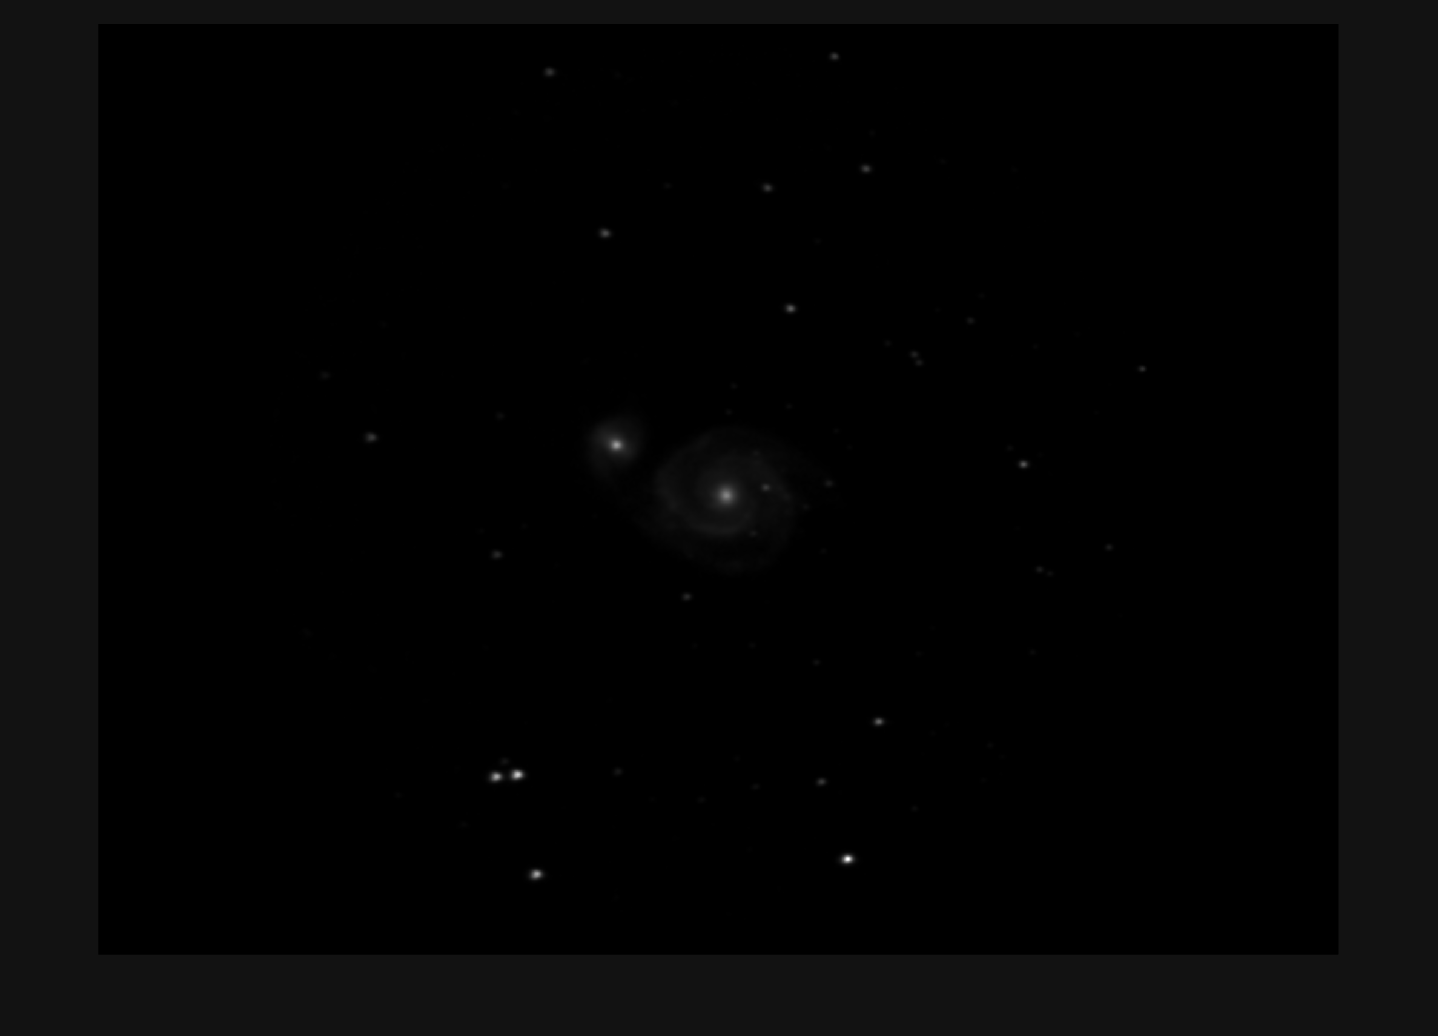

img_adj = zeros(size(img_denoised), 'like', img_denoised);
for k = 1:3
    ch = img_denoised(:,:,k);
    low_in = prctile(ch(:), 50);
    high_in = prctile(ch(:), 99.99);

    
    img_adj(:,:,k) = imadjust(img_denoised(:,:,k), [low_in, high_in], [0,1], .7);

    img_adj(:,:,k) = (img_adj(:,:,k)) .^.5;
end

img_adj = (img_adj ./ (scale_factor .^.8)) .* 2;


imshow(mask);

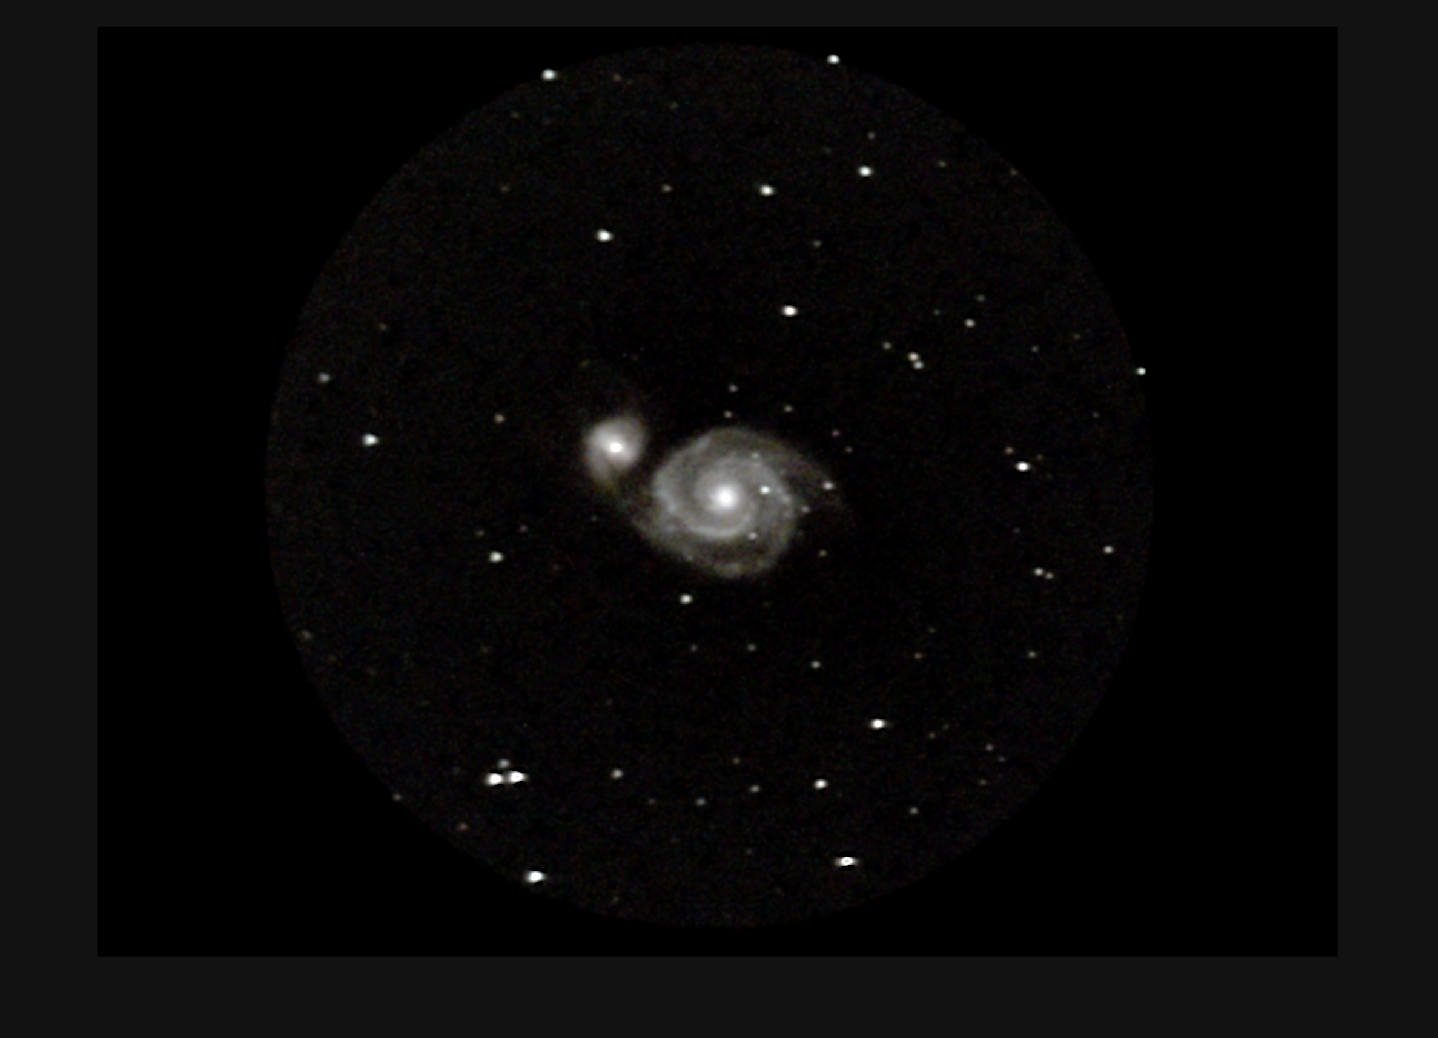

imshow(img_adj);

save_image(img_adj, "output/output.tif");

Colors

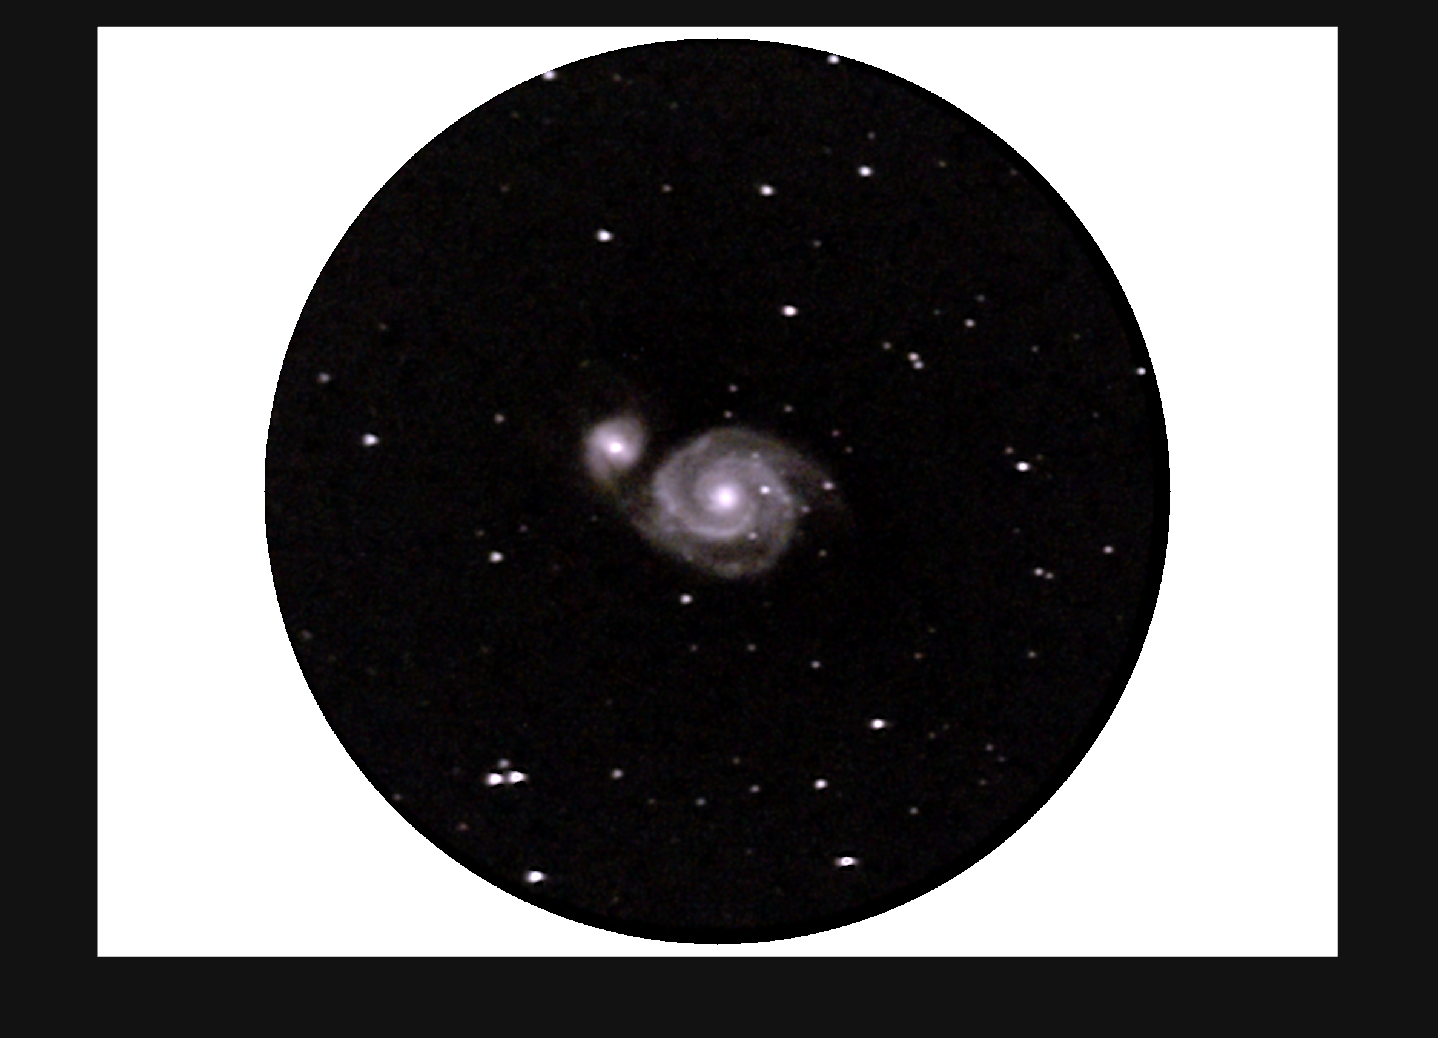

% Apply weights to the color channels for a nicer look
rgb_weights = [1.05, .95, 1.1];
img_rgb = img_adj;
for k = 1:3
    ch = img_rgb(:,:,k) .* rgb_weights(k);
    img_rgb(:,:,k) = ch;
end
imshow(circular_crop(img_rgb, 20, 1));

save_image(img_rgb, "output/output.tif");